### **Método de Newton-Raphson**** (Tangentes)**


$$x^{k+1} = x^{k}-\frac{f(x^{k})}{f'(x^{k})}$$


Vamos encontrar o zero da função $f(x) = -0.5x^{2}+2.5x+4.5$ no intervalo de $[-2.5,0]$utilizando o método de Newton-Raphson, com  chute inicial $x^{0} = -1$ e erro relativo igual ou menor que $10^{-4}$.

**Graficamente, **

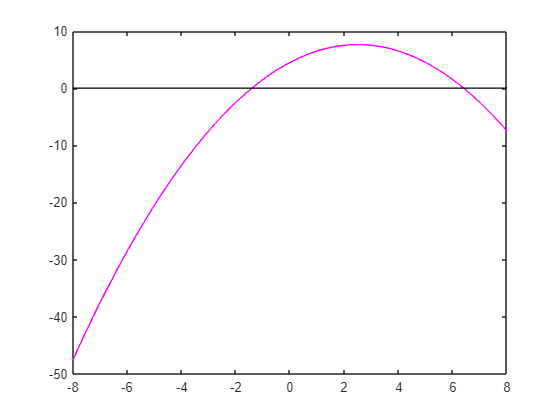

x= -8:0.01:8;
y = fun(x);
plot(x,y,'magenta')
y1 = 0*x;
hold on 
plot(x,y1, 'black')
hold off

**Implementação do MPF:**

format long
x0 = -1;
tol = 10^-4;
k = 0; % numero de interações 
er_rel= 10; % erro relativo inicial 
while (er_rel>tol)
    k = k+1;
    x = x0 - (fun(x0)/gfun(x0)); % Atualização 
    xk(k,:) = x0;
    fk(k, :) = fun(x0);
    er_rel = abs (x- x0)/abs(x);
    er_relk(k,:) = er_rel;
    x0=x;
end 
[xk, fk, er_relk]

ans =   -1.000000000000000   1.500000000000000   0.300000000000000
  -1.428571428571429  -0.091836734693878   0.016635859519409
  -1.405194805194805  -0.000273233260246   0.000049793877935


**Definindo as funções que serão utilizadas:**

function f1 = fun(x)
    f1 = -0.5*x.^2 +2.5*x + 4.5;
end
function g1 = gfun(x)
    g1 = -x + 2.5;
end
